5
30


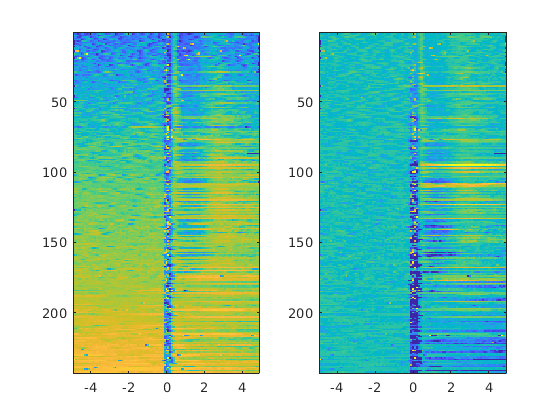

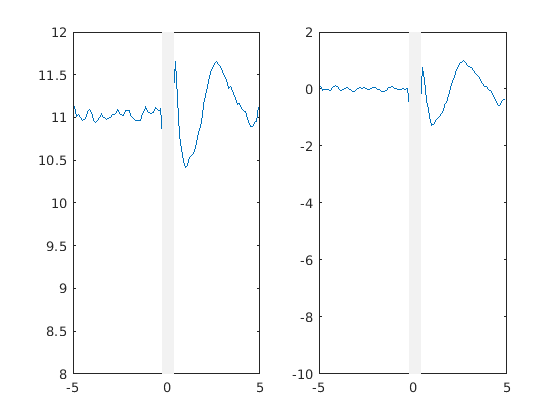

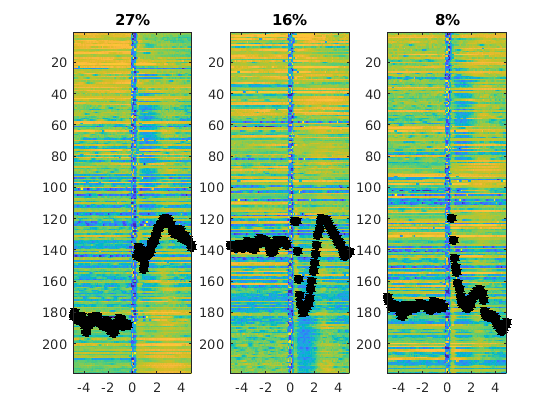

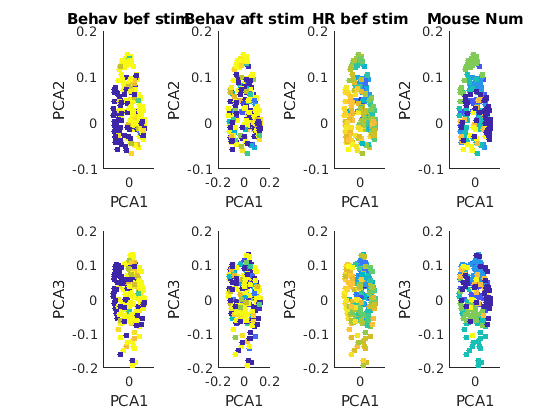

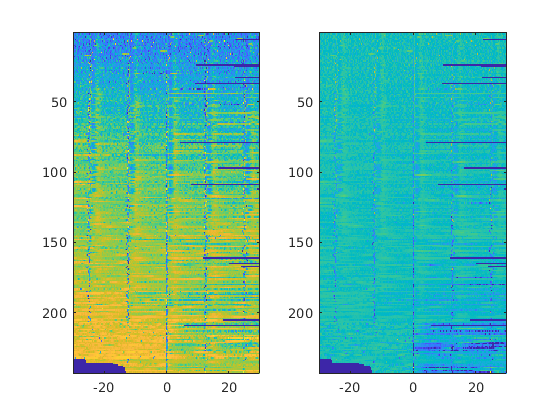

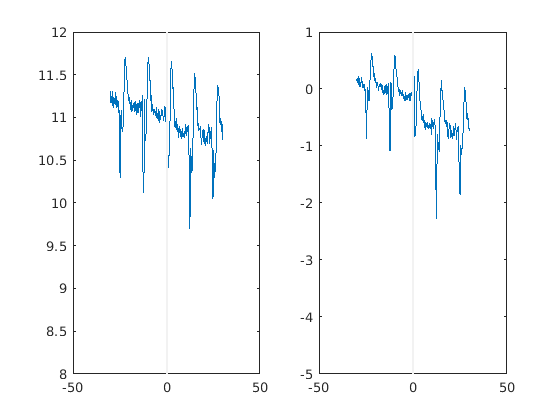

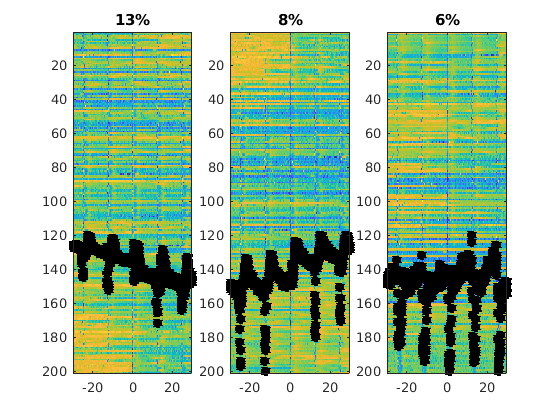

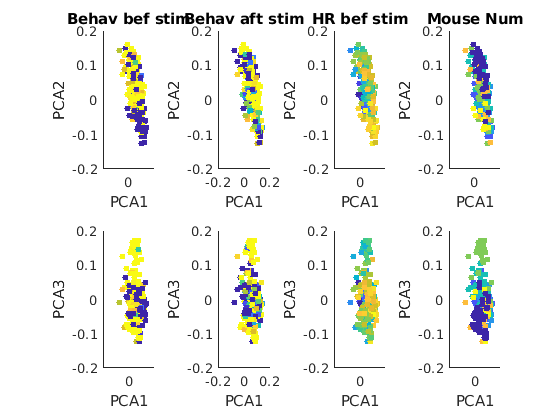

SessNames={'UMazeCond','UMazeCondNight' 'SoundCond' 'CtxtCond'}; %'UMazeCondBlockedShock_EyeShock' 'UMazeCondBlockedSafe_EyeShock'};
TimeLims=[5,30];
for tt=1:length(TimeLims)
    TimeLim=TimeLims(tt);
    disp(num2str(TimeLim))
    RemDat=[];
    RemFzTimeBef=[];    RemFzTimeAft=[];
    RemDatPos=[];

    RemMouseNum=[];
    tpsvect=[-TimeLim+0.1:0.1:TimeLim-0.1]*1e4;
    for ss=1:2%length(SessNames)
        Dir=PathForExperimentsEmbReact(SessNames{ss});
        MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
        Dir=RemoveElementsFromDir(Dir,'nmouse',MouseToAvoid);
        for d=1:length(Dir.path)
            Dat=[];
            FzTimeBef=[];FzTimeAft=[];
            MouseNum=[];
            
            for dd=1:length(Dir.path{d})
                cd(Dir.path{d}{dd})
                load('ExpeInfo.mat')
                if exist('HeartBeatInfo.mat')>0
                    clear EKG TTLInfo
                    load('HeartBeatInfo.mat')
                    load('behavResources_SB.mat')
                    TTLInfo.StimEpoch=mergeCloseIntervals(TTLInfo.StimEpoch,1*1e4);
                    EpAll=intervalSet(Start(TTLInfo.StimEpoch)-TimeLim*1e4,Start(TTLInfo.StimEpoch)+TimeLim*1e4);
                    EpBef=intervalSet(Start(TTLInfo.StimEpoch)-2*1e4,Start(TTLInfo.StimEpoch)-0.5*1e4);
                    EpAft=intervalSet(Start(TTLInfo.StimEpoch)+2*1e4,Start(TTLInfo.StimEpoch)+5*1e4);                    
                    for e=1:length(Start(TTLInfo.StimEpoch))
                        try
                            Times=Range(EKG.HBTimes);
                            HeartRate = tsd(Times(1:end-1),1./(diff(Times/1e4)));
                            dattemp=interp1(Range(Restrict(HeartRate,subset(EpAll,e)))-Start(subset(EpAll,e))-TimeLim*1E4,Data(Restrict(HeartRate,subset(EpAll,e))),tpsvect);
                            Dat=[Dat;dattemp];
                            tempEp=and(subset(EpBef,e),Behav.FreezeEpoch);
                            durtempEp=sum(Stop(tempEp,'s')-Start(tempEp,'s'));
                            FzTimeBef=[FzTimeBef,durtempEp];
                            tempEp=and(subset(EpAft,e),Behav.FreezeEpoch);
                            durtempEp=sum(Stop(tempEp,'s')-Start(tempEp,'s'));
                            FzTimeAft=[FzTimeAft,durtempEp];
                            MouseNum=[MouseNum,ExpeInfo.nmouse];
                            
                        end
                    end
                    
                end
            end
            
            if size(Dat,1)>5
                %             figure
                %             subplot(121)
                %             [MatNew,ind]=SortMat(Dat,[5:70]);
                %             imagesc(tpsvect,1:size(MatNew,1),MatNew)
                %             caxis([5 15])
                %             title(num2str(ExpeInfo.nmouse))
                %             subplot(122)
                %             imagesc(tpsvect,1:size(MatNew,1),nanzscore(MatNew',[5:70])')
                %             caxis([-10 10])
                if ss<3
                    RemDat=[RemDat;Dat];
                    RemFzTimeBef=[RemFzTimeBef,FzTimeBef];
                    RemFzTimeAft=[RemFzTimeAft,FzTimeAft];
%                     RemDatPos=[RemDatPos,DatPos];
                    RemMouseNum=[RemMouseNum,MouseNum];
                end
            end
        end
    end
    WinToExclude=[ceil(size(RemDat,2)/2)-2:ceil(size(RemDat,2)/2)+3];
    
    
    figure
    subplot(121)
    [MatNew,ind]=SortMat(RemDat,[4:ceil(size(RemDat,2)/2)-4]);
    imagesc(tpsvect/1e4,1:size(MatNew,1),MatNew)
    caxis([5 15])
    subplot(122)
    imagesc(tpsvect/1e4,1:size(MatNew,1),nanzscore(MatNew',[4:ceil(size(RemDat,2)/2)-4])')
    caxis([-10 10])
    
    figure
    subplot(121)
    plot(tpsvect/1e4,nanmean((RemDat)))
    patch([-0.2 -0.2 0.4 0.4],[min(ylim) max(ylim) max(ylim) min(ylim)],[1 1 1]*0.95,'EdgeColor',[1 1 1]*0.95),hold on
    caxis([5 15])
    subplot(122)
    plot(tpsvect/1e4,nanmean(nanzscore(RemDat',[4:ceil(size(RemDat,2)/2)-4])'))
    patch([-0.2 -0.2 0.4 0.4],[min(ylim) max(ylim) max(ylim) min(ylim)],[1 1 1]*0.95,'EdgeColor',[1 1 1]*0.95),hold on
    caxis([-10 10])
    
    RemDatPCA=RemDat;
    RemDatPCA(:,WinToExclude)=[];
    DatToPCA=nanzscore(RemDatPCA')';
    
    RemDatPCA=RemDat;
    RemFzTimeBefToPCA=RemFzTimeBef';
    RemFzTimeAftToPCA=RemFzTimeAft';
    MouseNumToPCA=RemMouseNum';
    RemDatPCA(sum(isnan(DatToPCA)')>0,:)=[];
    MouseNumToPCA(sum(isnan(DatToPCA)')>0,:)=[];
    RemFzTimeBefToPCA(sum(isnan(DatToPCA)')>0,:)=[];
    RemFzTimeAftToPCA(sum(isnan(DatToPCA)')>0,:)=[];
    DatToPCA(sum(isnan(DatToPCA)')>0,:)=[];
    
    [EigVect,EigVals]=PerformPCA(DatToPCA);
    figure
    for k=1:3
        EigVect(:,k)=EigVect(:,k)*sign(sum(EigVect(:,k)));
        subplot(1,3,k)
        [MatNew,ind]=SortMat([EigVect(:,k),RemDatPCA],1);
        MatNew(:,1)=[];
        imagesc(tpsvect/1e4,1:size(MatNew,1),MatNew)
        hold on
        Proj=RemDatPCA'*EigVect(:,k);
        Proj=Proj./(max(Proj)-min(Proj));Proj=Proj-min(Proj);
        Proj(WinToExclude)=NaN;
        plot(tpsvect/1e4,-Proj*80+200,'*','linewidth',3,'color','k')
        title([num2str(floor(100*EigVals(k)/sum(EigVals))) '%'])
        caxis([5 15])
    end
    [id,out,out2]=unique(MouseNumToPCA);
    figure
    subplot(2,4,1)
    scatter(EigVect(:,1),EigVect(:,2),20,RemFzTimeBefToPCA,'filled')
    xlabel('PCA1'),ylabel('PCA2')
    title('Behav bef stim')
    subplot(2,4,5)
    scatter(EigVect(:,1),EigVect(:,3),20,RemFzTimeBefToPCA,'filled')
    xlabel('PCA1'),ylabel('PCA3')
    subplot(2,4,2)
    scatter(EigVect(:,1),EigVect(:,2),20,RemFzTimeAftToPCA,'filled')
    xlabel('PCA1'),ylabel('PCA2')
    title('Behav aft stim')
    subplot(2,4,6)
    scatter(EigVect(:,1),EigVect(:,3),20,RemFzTimeAftToPCA,'filled')
    xlabel('PCA1'),ylabel('PCA3') 
    subplot(2,4,3)
    scatter(EigVect(:,1),EigVect(:,2),20,nanmean(RemDatPCA(:,4:ceil(size(RemDat,2)/2)-4)'),'filled')
    xlabel('PCA1'),ylabel('PCA2')
    title('HR bef stim')
    subplot(2,4,7)
    scatter(EigVect(:,1),EigVect(:,3),20,nanmean(RemDatPCA(:,4:ceil(size(RemDat,2)/2)-4)'),'filled')
    xlabel('PCA1'),ylabel('PCA3')
    subplot(2,4,4)
    scatter(EigVect(:,1),EigVect(:,2),20,out2,'filled')
    xlabel('PCA1'),ylabel('PCA2')
    title('Mouse Num')
    subplot(2,4,8)
    scatter(EigVect(:,1),EigVect(:,3),20,out2,'filled')
    xlabel('PCA1'),ylabel('PCA3')
end

SessNames={ 'UMazeCond_EyeShock' 'UMazeCondBlockedShock_EyeShock' 'UMazeCondBlockedSafe_EyeShock'};
TimeLims=[8];
for tt=1:length(TimeLims)
    TimeLim=TimeLims(tt);
    disp(num2str(TimeLim))
    RemDat=[];
    RemFzTimeBef=[];    RemFzTimeAft=[];
    
    RemMouseNum=[];
    tpsvect=[-TimeLim+0.1:0.1:TimeLim-0.1]*1e4;
    for ss=1:3
        Dir=PathForExperimentsEmbReact(SessNames{ss});
        MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
        Dir=RemoveElementsFromDir(Dir,'nmouse',MouseToAvoid);
        for d=1:length(Dir.path)
            Dat=[];
            FzTimeBef=[];FzTimeAft=[];
            MouseNum=[];
            
            for dd=1:length(Dir.path{d})
                cd(Dir.path{d}{dd})
                load('ExpeInfo.mat')
                if exist('HeartBeatInfo.mat')>0
                    clear EKG TTLInfo
                    load('HeartBeatInfo.mat')
                    load('behavResources.mat')
                    TTLInfo.StimEpoch=mergeCloseIntervals(TTLInfo.StimEpoch,1*1e4);
                    EpAll=intervalSet(Start(TTLInfo.StimEpoch)-TimeLim*1e4,Start(TTLInfo.StimEpoch)+TimeLim*1e4);
                    EpBef=intervalSet(Start(TTLInfo.StimEpoch)-2*1e4,Start(TTLInfo.StimEpoch)-0.5*1e4);
                    EpAft=intervalSet(Start(TTLInfo.StimEpoch)+2*1e4,Start(TTLInfo.StimEpoch)+5*1e4);
                    for e=1:length(Start(TTLInfo.StimEpoch))
                        try
                            Times=Range(EKG.HBTimes);
                            HeartRate = tsd(Times(1:end-1),1./(diff(Times/1e4)));
                            dattemp=interp1(Range(Restrict(HeartRate,subset(EpAll,e)))-Start(subset(EpAll,e))-TimeLim*1E4,Data(Restrict(HeartRate,subset(EpAll,e))),tpsvect);
                            Dat=[Dat;dattemp];
                            tempEp=and(subset(EpBef,e),Behav.FreezeEpoch);
                            durtempEp=sum(Stop(tempEp,'s')-Start(tempEp,'s'));
                            FzTimeBef=[FzTimeBef,durtempEp];
                            tempEp=and(subset(EpAft,e),Behav.FreezeEpoch);
                            durtempEp=sum(Stop(tempEp,'s')-Start(tempEp,'s'));
                            FzTimeAft=[FzTimeAft,durtempEp];
                            MouseNum=[MouseNum,ExpeInfo.nmouse];
                            
                        end
                    end
                end
            end
            
            RemDat=[RemDat;Dat];
            RemFzTimeBef=[RemFzTimeBef,FzTimeBef];
            RemFzTimeAft=[RemFzTimeAft,FzTimeAft];
            RemDatPos=[RemDatPos,DatPos];
            RemMouseNum=[RemMouseNum,MouseNum];
        end
    end
end

8


Undefined function or variable 'RemDatPos'.


figure
RemDat(RemDat<11)=NaN;
[hl,hp]=boundedline(tpsvect/1e4,nanmean(RemDat),[stdError(RemDat);stdError(RemDat)]','alpha'),hold on
patch([-0.3 -0.3 0.4 0.4],[min(ylim) max(ylim) max(ylim) min(ylim)],[1 1 1]*0.95,'EdgeColor',[1 1 1]*0.95),hold on
ylim([12.2 14])


